# 案例：黄金分割法求区间最小值点

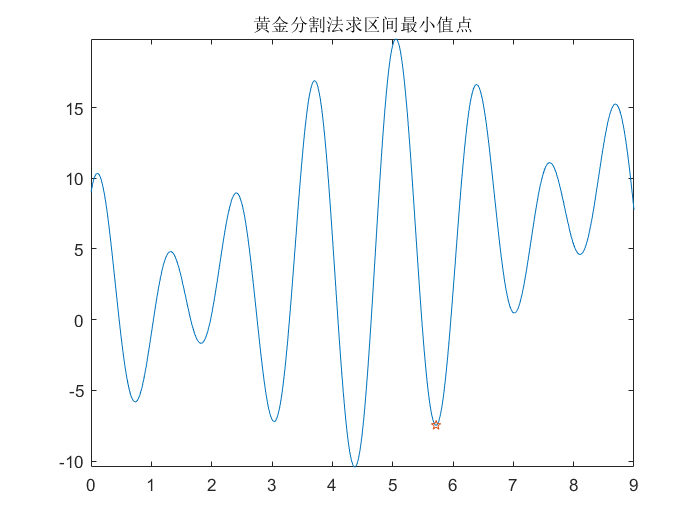

clear; clc;
fun = @(x) x + 6 * sin(4 * x) + 9 * cos(5 * x);
x0 = OptGold(fun, 0, 9, 1e-4, 1e-5, 1000);
fplot(fun, [0, 9])
hold on 
plot(x0, fun(x0), 'p');
hold off
title('黄金分割法求区间最小值点');

function x0 = OptGold(fun, a, b, TolX, TolFun, MaxIter)
%{
函数功能：黄金分割法求区间最小值点；
输入：
  fun：目标函数句柄；
  a：左端点值；
  b：右端点值；
  TolX：x 精度阈值；
  TolFun：y 精度阈值；
  MaxIter：最大迭代次数；
输出：
  x0：最小值点；
%}
if nargin < 6
   MaxIter = 1000;
end
if nargin < 5
   TolFun = 1e-6;
end
if nargin < 4
   TolX = 1e-6;
end
if nargin < 3
   error('输入参数不足！');
end
% 初始情况
a1 = a + 0.382*(b - a);
a2 = a + 0.618*(b - a);
f1 = fun(a1);
f2 = fun(a2);
ite = 0;
while abs(b - a) >= TolX || abs(f1 - f2) >= TolFun && ite < MaxIter
   if f1 < f2
      b = a2;
      a2 = a1;
      f2 = f1;
      a1 = a + 0.382 * (b - a);
      f1 = fun(a1);
   else
      a = a1;
      a1 = a2;
      f1 = f2;
      a2 = a + 0.618 * (b - a);
      f2 = fun(a2);
   end
   ite = ite + 1;
   if ite == MaxIter
      disp('没有找到最小值！');
      x0 = NaN;
      return;
   end
end
x0 = 0.5 * (a + b);
end

function x0 = OptGolden(fun, a, b, TolX, TolFun, MaxIter)
%{
函数功能：黄金分割法求区间最小值点；
输入：
  fun：目标函数句柄；
  a：左端点值；
  b：右端点值；
  TolX：x 精度阈值；
  TolFun：y 精度阈值；
  MaxIter：最大迭代次数；
输出：
  x0：最小值点；
%}
if nargin < 6
   MaxIter = 1000;
end
if nargin < 5
   TolFun = 1e-6;
end
if nargin < 4
   TolX = 1e-6;
end
if nargin < 3
   error('输入参数不足！');
end
% 初始情况
c = a + 0.382 * (b - a);
d = a + 0.618 * (b - a);
fc = fun(c);
fd = fun(d);
if MaxIter <= 0 || (abs(b - a) < TolX && abs(fc - fd) < TolFun)
    if fc <= fd
        x0 = c;
    else
        x0 = d;
    end
else
    if fc < fd
        x0 = OptGolden(fun, a, d, TolX, TolFun, MaxIter - 1);
    else
        x0= OptGolden(fun, c, b, TolX, TolFun, MaxIter - 1);
    end
end
end